## **PL 3 Variáveis e Distribuições Aleatórias**

#### **Ex1. **Variável aleatória X correspondente à face que sai no lançamento de um dado.

a) Gráfico da função massa de probabilidade de x:

x = 1:6;
prob_x = ones(1,6) * 1/6;

stem(x,prob_x);
ylim([0 0.4]);
grid on;

b) Gráfico em subplot com o anterior da função de distribuição cumulativa de x:

x = 1:6;
prob_x = ones(1,6) * 1/6;
xx = [0 x 7];
prob_xx = [0 prob_x 0];

stairs(xx, cumsum(prob_xx));
ylim([0 1.1]);
xlim([0 8]);
grid on;

#### **Ex2. **Caixa contém noventa notas de 5, nove notas de 50 e uma nota de 100.

a) Espaço de amostragem da experiência aleatória "retirar uma nota da caixa" e probabilidades dos acontecimentos elementares.

**R:** S = {nota1, nota2, ..., nota99, nota100}                     % espaço de amostragem

b) Variável aleatória X (valor de uma qualquer nota retirada da caixa. Seu espaço de amostragem e função massa de probabilidade de X.

**R: **Sx = {5, 50, 100}

% x1 = 5;
% x2 = 50;
% x3 = 100;
prob_x1 = 90/100
prob_x2 = 9/100
prob_x3 = 1/100

c) Função de distribuição acumulada de X, Fx(x):

x = [5 50 100];
prob_x = [0.9 0.09 0.01];
xx = [0 x 120];
prob_xx = [0 prob_x 0];

%% cumsum = cumulative sum
stairs(xx, cumsum(prob_xx))
ylim([0 1.1]);
xlim([0 120]);
xticks([0 5 50 100]);
grid on;

#### **Ex3. **Quatro lançamentos de moeda equilibrada. X a variável aleatória que representa o nº de coroas observadas nos quatro lançamentos.

a) Função massa de probabilidade Px(x) da variável aleatória X obtida por simulação:

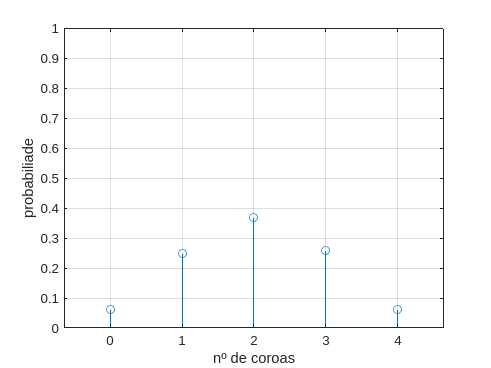

numExp = 1e4;
nLanc = 4;
% num de coroas pode ser de 0 a 4;
x = 0:1:4;
vetorNumCoroas = zeros(1,nLanc + 1);

for i = 1:numExp
    matrizLanc = rand(1,4) < 0.5;
    numCoroas = sum(matrizLanc);
    vetorNumCoroas(numCoroas + 1) = vetorNumCoroas(numCoroas + 1) + 1;
end

vetorMassaProb_x = vetorNumCoroas/numExp;

stem(x,vetorMassaProb_x);
ylim([0 1]);
xlabel('nº de coroas');
ylabel('probabiliade');
grid on;

b) Estimar o valor esperado, a variância e o desvio padrão de X com base em Px(x).

- O **valor esperado**, **E|X|**, de uma variável aleatória X é dado por:

**E[X]= (n) i=0 ∑ xi⋅p_x(xi)**, onde     

                                                                - xi são os valores possíveis da variável aleatória X

                                                                - p(xi) são as probabilidades associadas a cada valor xi

- A **variância**, **Var(X)**, de uma variável aleatória X é dada por:

**Var(X) = E[X²] - (E[X])²**

- O **desvio** **padrão**, σ(X), é dada por:

**sqrt(Var(X))**

% valor esperado:
x = 0:1:4;
numLanc = 4;
% do exercicio anterior, um dos resultados do vetor de probabilidades deu:
prob_a = [0.0642 0.2494 0.3743 0.2513 0.0608];
valorEsperado = 0;
valorEsperado_x2 = 0;

% valor esperado
for i = 1:length(x)
    valorEsperado = valorEsperado + x(i) * prob_a(i);
end

% variância
for i = 1:length(x)
    valorEsperado_x2 = valorEsperado_x2 + x(i)^2 * prob_a(i);
end
variancia = valorEsperado_x2 - valorEsperado^2;

% desvio padrão
desvioPadrao = sqrt(variancia);

disp(['valor esperado: ', num2str(valorEsperado)]);

valor esperado: 1.9951


disp(['variância: ', num2str(variancia)]);

variância: 1.0007


disp(['desvio padrão: ', num2str(desvioPadrao)]);

desvio padrão: 1.0003


c) Tipo da distribuição da variável aleatória X e qual a expressão teórica da sua função de probabilidade

**R:** Distribuição discreta (fruto de contagem).

% expressão..???

d) Calcular os valores teóricos de a) e comparar com o obtido na simulação

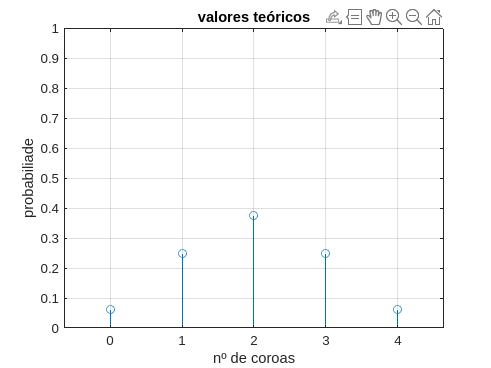

x = 0:1:4;
vetorProbT = zeros(1,5);
n = 4;
prob = 0.5;

function y = coefBinomial(n,k)
    y = factorial(n)/(factorial(k)*(factorial(n - k)));
end
% prob = prob de coroa (0.5)
% k = numero de coroas (está no X para cada situaçao)
% n = numero de lançamentos
% prob(xi) = factorial(n)/(factorial(k)*(factorial(n - k))) *
%            prob^k  * (1 - prob)^(n-k)
for i = 1:length(vetorProbT)
    vetorProbT(i) = coefBinomial(n,x(i)) * prob^x(i) * (1 - prob)^(n - x(i));
end

stem(x,vetorProbT);
ylim([0 1]);
title('valores teóricos');
xlabel('nº de coroas');
ylabel('probabiliade');
grid on;

**R: **Na alínea a) ---- um dos resultados: [0.0642 0.2494 0.3743 0.2513 0.0608] ---- os resultados rondam os valores teóricos, mas obviamente há sempre alguma diferença no que é obtido. No caso dos valores teóricos, a chance de zero e quatro coroas é igual, bem como a chance de 1 ou 3 coroas (visto que são casos complementares/opostos),

e)  Valores teóricos de E[X] e de Var(X) e comparar com a alínea b).